# Robot Médico DaVinci

# Definir brazo PSM, herramientas Snake y Caudier

Dificultad: Alta (Avanzado)

clear all
close all
% actdir= '.\ScriptPropios';
% addpath(actdir)

deg= pi/180;


## Introducción

- El robot médico DaVinci consta de una serie de brazos robóticos para poner los elementos PSM en su posición inicial. Estos brazos podrían ser cualquier robot, por ejemplo, el Gofa.

- Una vez que el elemento PSM está en su posción inicial, en el lugar en el cuerpo donde se quiere operar, se fijan los brazos del robot externo y solo se mueve las articulaciones del PSM.

- Las herramientas del brazo PSM son de dos tipos, los ToolSnake que son unas tijeras con varias articulaciones anteriores y los ToolCaudier que son unas pinzas con articulaciones previas.

- Normalmente el DaVinci tiene tres elementos PSM, uno con las tijeras, otro con la pinza y un tercero con la cámara para ver la operación.

## Modelo PSM

- El modelo PSM tiene una estructura cerrada que no va a ser modelada en SImScape.

- Las articulaciones 12 y 13 son equivalentes a las 2 y 3. De hecho son de adorno ya que no mueven nada más que su brazo correspondiente, mientras que la 2 y 3 mueven el resto del robot.

- Por ello, se pueden quitar del modelo en RigidBody y en el esquema MultiBody darlas el mismo valor que a la 2 y 3.

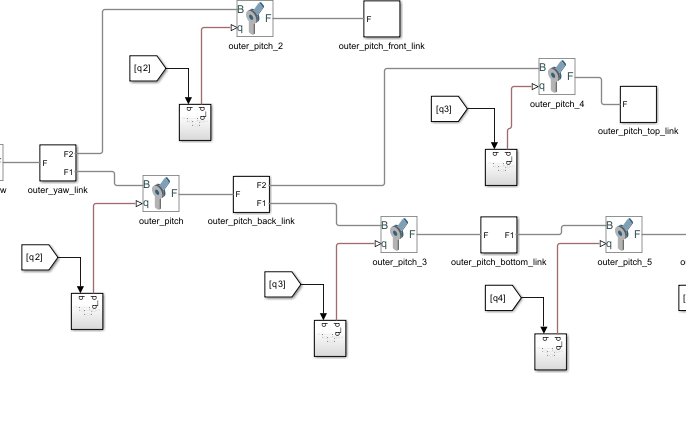

deg= pi/180;
Estacion= 'M05S1_PSM';
open_system(Estacion)
% Se inicia la clase con el robot con el interface de simulink
% VER VERSIÓN SIMULINK
% Variables de simulink

% Posición inicial del robot y del rastreador
% Estas variables van a ser usadas por los objetos Kin como variables del sistema 
% No deben modificarse en el programa 
q0_= zeros(1,6);
pose_= randn(3,3)*1e-3;

% Posición de la base del robot
baseRobot= [[0,0,0]*1e-3, [0,0,0]*deg];
Carga= Pieza('Null');
Carga.Color([1,0,0,0.7]);

open_system(Estacion)

% Paso de la estación de simulink al objeto Rigid Body (Robotic Toolbox)
robot= importrobot(Estacion);
robot.showdetails

--------------------
Robot: (13 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  
   2        Body02        Joint02       revolute            Body01(1)   Body03(3)  Body13(13)  
   3        Body03        Joint03       revolute            Body02(2)   Body04(4)  Body12(12)  
   4        Body04        Joint04       revolute            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06      prismatic            Body05(5)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   Body08(8)  
   8        Body08        Joint08          fixed            Body07(7)   Body09(9)  
   9        Body09        Joint09          fixed            Body08(8)   Body10(10)  


% Para recordar a que body pertenece las herramientas y cargas deseadas
% Es preciso mirarlo dentro de la estructura

% Esas articulaciones son de adorno. Se mueven de la misma forma que las
% verdaderas

removeBody(robot,'Body12');
removeBody(robot,'Body13');
robot.showdetails

--------------------
Robot: (11 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  
   2        Body02        Joint02       revolute            Body01(1)   Body03(3)  
   3        Body03        Joint03       revolute            Body02(2)   Body04(4)  
   4        Body04        Joint04       revolute            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06      prismatic            Body05(5)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   Body08(8)  
   8        Body08        Joint08          fixed            Body07(7)   Body09(9)  
   9        Body09        Joint09          fixed            Body08(8)   Body10(10)  
  10        Body10      


TcpCarga= 'Body11';
TcpPinza= 'Body12';

% Abrir fichero simulink
% Se debe definir el rigid-body asociado a la estación, la estación simulink
% la herramienta deseada (última por defecto) y el valor de los ejes
% iniciales q0= [0,0,0,0,0,0] por defecto
q0= zeros(1,6); % La variable de entrada
q0_= zeros(1,6); % La variable de entrada en simulink para todos los posibles robots
rob= Cin(robot, Estacion, TcpCarga, q0);

Herramienta: Body11
Simulación. Ts= 0.100 m/s


### 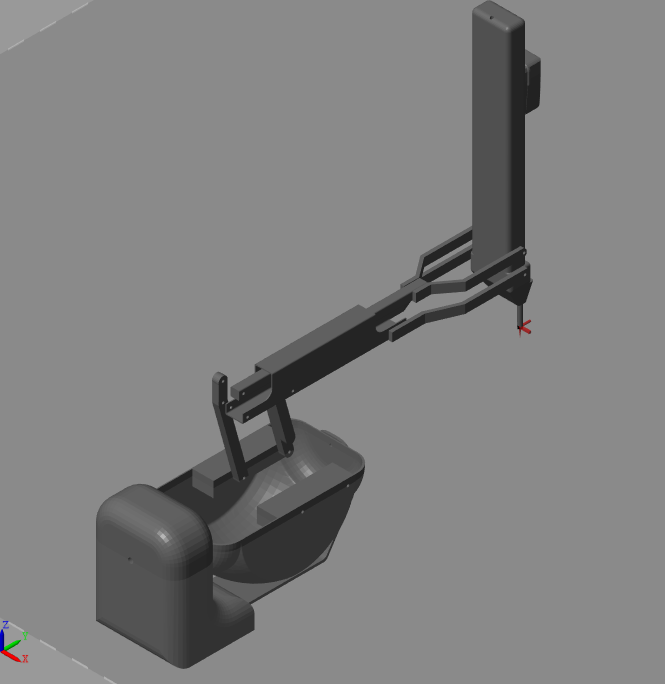

### Guardar el robot en un subsistema y los datos en fichero *.mat

- Para no tener que repetir esta operación en otros modelos, se graba un subsistema con la estructura del robot Med_PSM y un fichero *mat con los datos.

- A partir de ahora, se va a usar estos datos para crear nuevos modelos.



%save('Med_PSM', 'robot', 'baseRobot', 'Carga', 'TcpPinza', "TcpCarga", "q0")


### Cinemática directa e inversa

% Hay dos articulaciones redundantes, la 3,2.
% Las dos últimas no se usan

q=  [[40,30,0,0]*deg,0e-3,70*deg];
rob.MoveAbsJ(q);



q=  [[0,20,0,0]*deg,0e-3,0*deg];
rob.MoveAbsJ(q);
q=  [[0,20,0,0]*deg,200e-3,0*deg];
rob.MoveAbsJ(q);


punto= rob.Pose


appMover

## Modelo ToolSnake

- Es la herramienta del robot para cortar.

- Es una tijera con una serie de ejes para girar la misma en el sentido que se desee.

Estacion= 'M05S2_ToolSnake.slx';

punto =    -0.0003    0.3875   -0.1953    1.5708    0.3491    3.1416


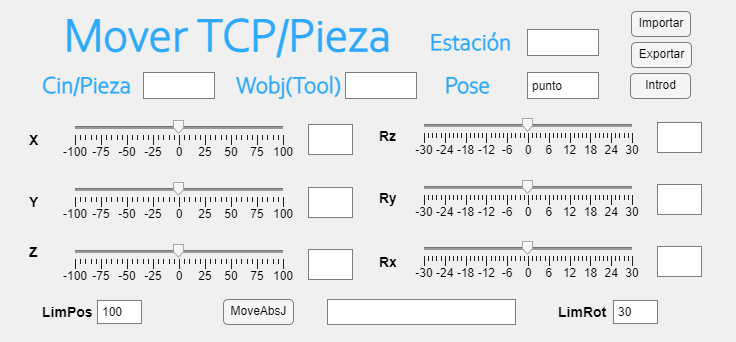

%open(Estacion)
% Se inicia la clase con el robot con el interface de simulink
% VER VERSIÓN SIMULINK

% Variables de simulink

% Posición inicial del robot y del rastreador
% Estas variables van a ser usadas por los objetos Kin como variables del sistema 
% No deben modificarse en el programa 
q0_= zeros(1,5);
pose_= randn(3,3)*1e-3;

% Posición de la base del robot
baseRobot= [[0,0,0]*1e-3, [0,0,0]*deg];

Carga= Pieza('Null');
Carga.Color([1,0,0,0.7]);
open_system(Estacion)


% Paso de la estación de simulink al objeto Rigid Body (Robotic Toolbox)
robot= importrobot(Estacion);
robot.showdetails

% Abrir fichero simulink
removeBody(robot, 'Body9');
robot.showdetails
q0= [0,0,0,0,30]*deg; % La variable de entrada
q0_= q0; % La variable de entrada en simulink para todos los posibles robots
TcpCarga= 'Body7';
TcpPinza= 'Body6';

--------------------
Robot: (9 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1         fixed             Base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  Body8(8)  Body9(9)  
   6        Body6        Joint6         fixed            Body5(5)   Body7(7)  
   7        Body7        Joint7         fixed            Body6(6)   
   8        Body8        Joint8      revolute            Body5(5)   
   9        Body9        Joint9      revolute            Body5(5)   
--------------------


rob= Cin(robot, Estacion, TcpCarga, q0);

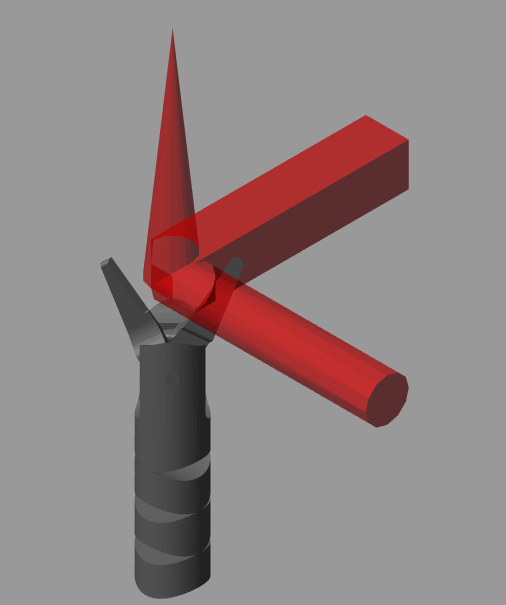

### Crear subsistema y fichero *.mat


%save('Med_Snake', 'robot', 'baseRobot', 'Carga', 'TcpPinza', "TcpCarga", "q0")


--------------------
Robot: (8 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1         fixed             Base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  Body8(8)  
   6        Body6        Joint6         fixed            Body5(5)   Body7(7)  
   7        Body7        Joint7         fixed            Body6(6)   
   8        Body8        Joint8      revolute            Body5(5)   
--------------------


### Cinemática directa


ejes= [30,30,30,30,30]*deg;

rob.MoveAbsJ(ejes);

Herramienta: Body7
Simulación. Ts= 0.100 m/s


### Modelo ToolCaudier

- Es la herramienta pinza para agarrar los que se desee cortar.

- Si se desea que la apertura sea simétrica nos sobra una articulación en RigidBody. En MultiBody se acciona las dos articulaciones con la misma entrada.

Estacion= 'M05S2_ToolCaudier.slx';
open(Estacion)
% Se inicia la clase con el robot con el interface de simulink
% VER VERSIÓN SIMULINK
% Variables de simulink

% Posición inicial del robot y del rastreador
% Estas variables van a ser usadas por los objetos Kin como variables del sistema 
% No deben modificarse en el programa 
q0_= zeros(1,3);
pose_= randn(3,3)*1e-3;

% Posición de la base del robot
baseRobot= [[0,0,0]*1e-3, [0,0,0]*deg];

open_system(Estacion)

% Paso de la estación de simulink al objeto Rigid Body (Robotic Toolbox)
robot= importrobot(Estacion);
robot.showdetails
% Para recordar a que body pertenece las herramientas y cargas deseadas
% Es preciso mirarlo dentro de la estructura

removeBody(robot, 'Body5');

robot.showdetails;
TcpCarga= 'Body7';
TcpPinza= 'Body6';
% Abrir fichero simulink

q0= [0,0,30]*deg; % La variable de entrada
q0_= q0; % La variable de entrada en simulink para todos los posibles robots
rob= Cin(robot, Estacion, TcpCarga, q0);

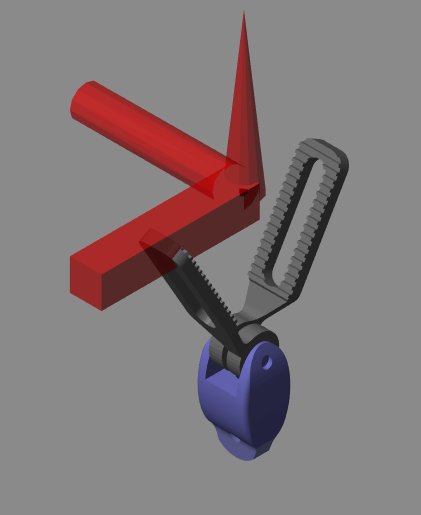

### Cinemática directa

ejes= [0,0,30]*deg;
rob.MoveAbsJ(ejes);

--------------------
Robot: (7 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1         fixed             Base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  Body5(5)  Body6(6)  
   4        Body4        Joint4      revolute            Body3(3)   
   5        Body5        Joint5      revolute            Body3(3)   
   6        Body6        Joint6         fixed            Body3(3)   Body7(7)  
   7        Body7        Joint7         fixed            Body6(6)   
--------------------


### Grabar subsistema y fichero *.mat


%save('Med_Caudier', 'robot', 'baseRobot', 'Carga', 'TcpPinza', "TcpCarga", "q0")


## Crear robots suma de PSM-Snake y PSM-Caudier

- Se va a obtener dos robots como suma del brazo PSM y las herramientas Snake y Caudier.

- Esta unión se puede hacer a partir de los ficheros *.mat para crear uno nuevo y de los subsistemas de simulink para crear uno nuevo.

- Se elimina la herramienta de PSM, y se le suma el Snake y Caudier en su extremo. Lo mismo se hace en el subsistema.

r1= load('Med_PSM')

--------------------
Robot: (6 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1         fixed             Base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  Body6(5)  
   4        Body4        Joint4      revolute            Body3(3)   
   5        Body6        Joint6         fixed            Body3(3)   Body7(6)  
   6        Body7        Joint7         fixed            Body6(5)   
--------------------


r1.robot.showdetails
r2= load('Med_Caudier')
r2.robot.showdetails



removeBody(r1.robot, 'Body11')
addSubtree(r1.robot, 'Body10', r2.robot);

Herramienta: Body7
Simulación. Ts= 0.100 m/s


r1.robot.showdetails


robot= r1.robot;
baseRobot= zeros(1,6);
Carga= Pieza('Null');
Carga.Color([1,0,0,0.7]);
TcpPinza= 'Body6';
TcpCarga= 'Body7';
q0= [r1.q0, r2.q0];
%save('Med_PSM_Caudier', 'robot', 'baseRobot', 'Carga', 'TcpPinza', "TcpCarga", "q0")
